clear, close all, clc

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



sig_data = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');

bkgnd_data = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

histogram(sig_data(1,:),30);
hold on
title('Pt')
histogram(bkgnd_data(1,:),30);
legend('Background','Signal')
x_range = [1013 1081];
[n_back_pt, n_sig_pt, ratio_pt] = n_calc(bkgnd_data(1,:), sig_data(1,:), x_range)

n_back_pt = 37871

n_sig_pt = 27011

ratio_pt = 0.7132

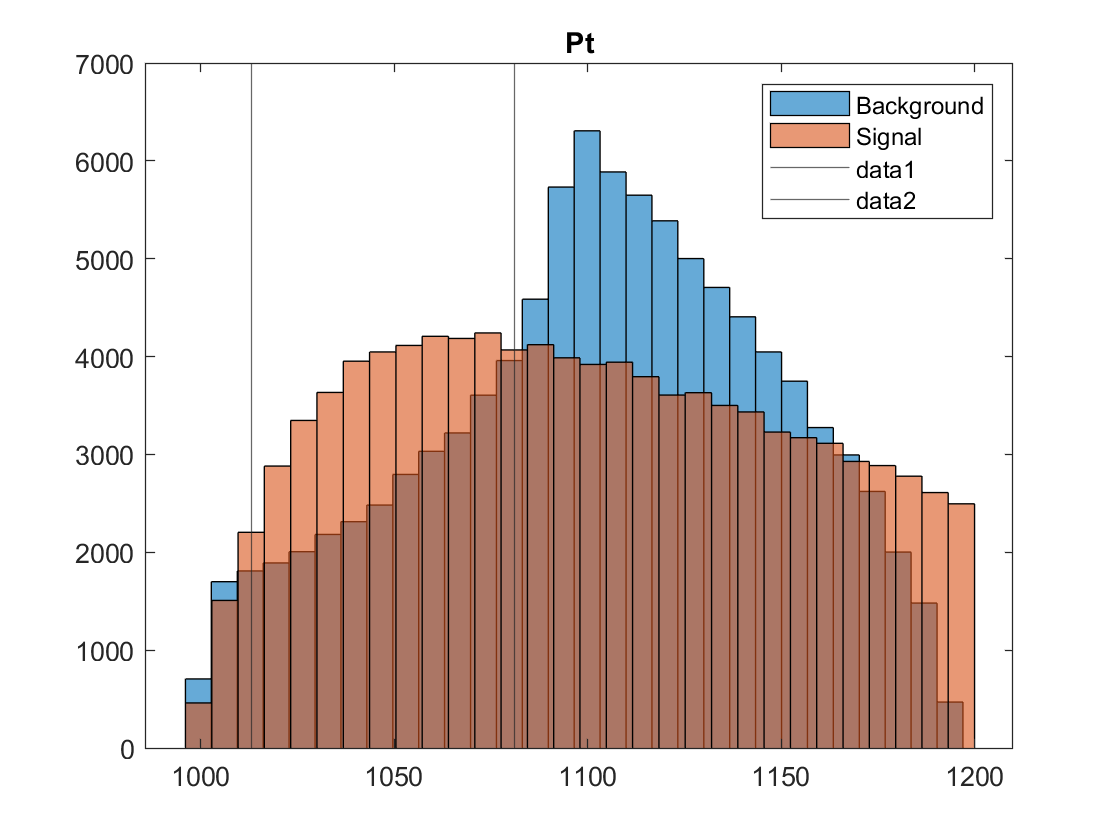

xline(x_range(1))
xline(x_range(2))
hold off

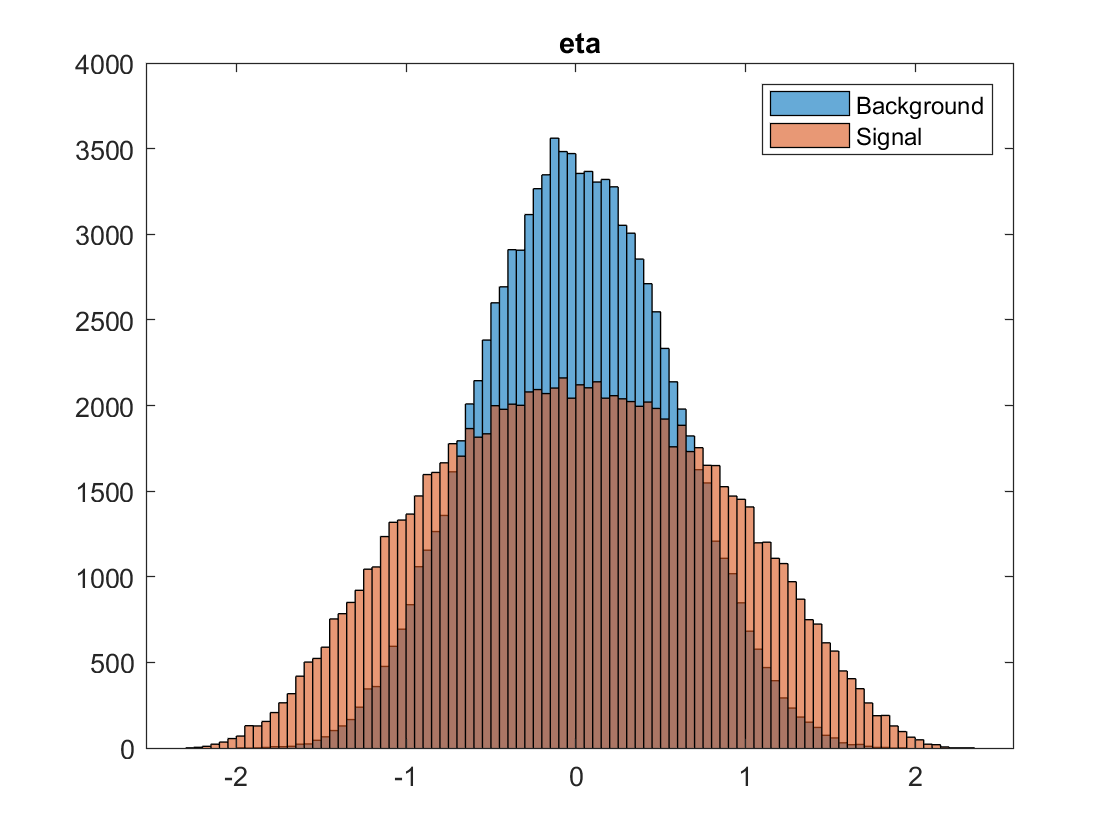


histogram(sig_data(2,:))
title('eta')
hold on
histogram(bkgnd_data(2,:))
hold off
legend('Background','Signal')

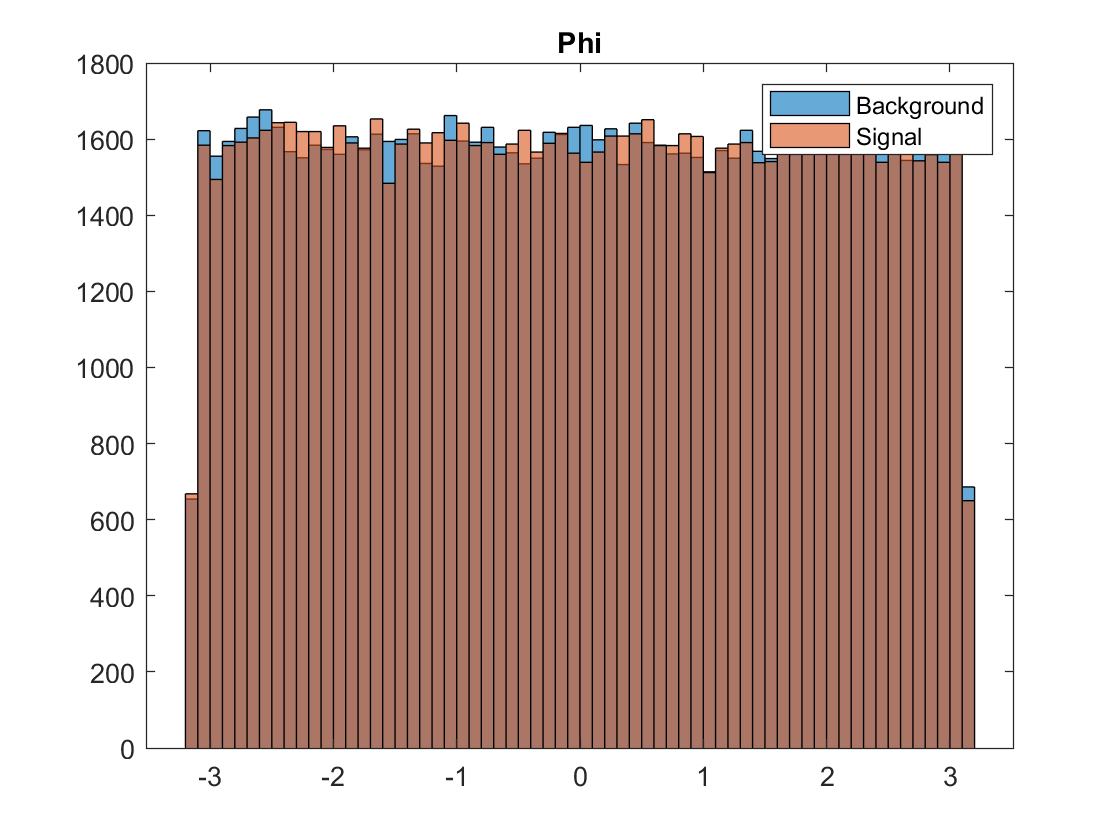


histogram(sig_data(3,:))
title('Phi')
hold on
histogram(bkgnd_data(3,:))
hold off
legend('Background','Signal')


histogram(sig_data(4,:))
title('Mass')
hold on
histogram(bkgnd_data(4,:))
legend('Background','Signal')
x_range = [120 130];
[n_back_mass, n_sig_mass, ratio_mass] = n_calc(bkgnd_data(4,:), sig_data(4,:), x_range)

n_back_mass = 6414

n_sig_mass = 75829

ratio_mass = 11.8224

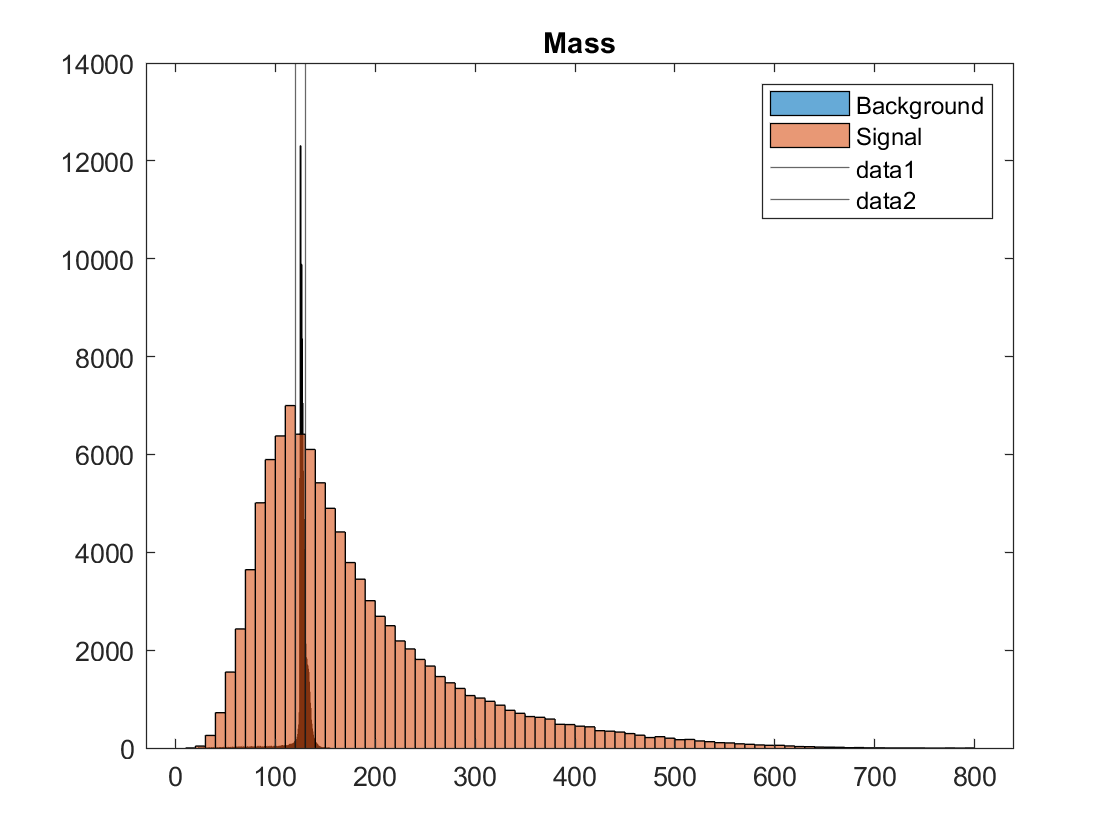

xline(x_range(1))
xline(x_range(2))
hold off


histogram(sig_data(5,:))
title('ee2')
hold on
histogram(bkgnd_data(5,:))
legend('Background','Signal')
x_range = [0.05 0.065];
[n_back_pt, n_sig_pt, ratio_pt] = n_calc(bkgnd_data(5,:), sig_data(5,:), x_range)

n_back_pt = 10137

n_sig_pt = 60170

ratio_pt = 5.9357

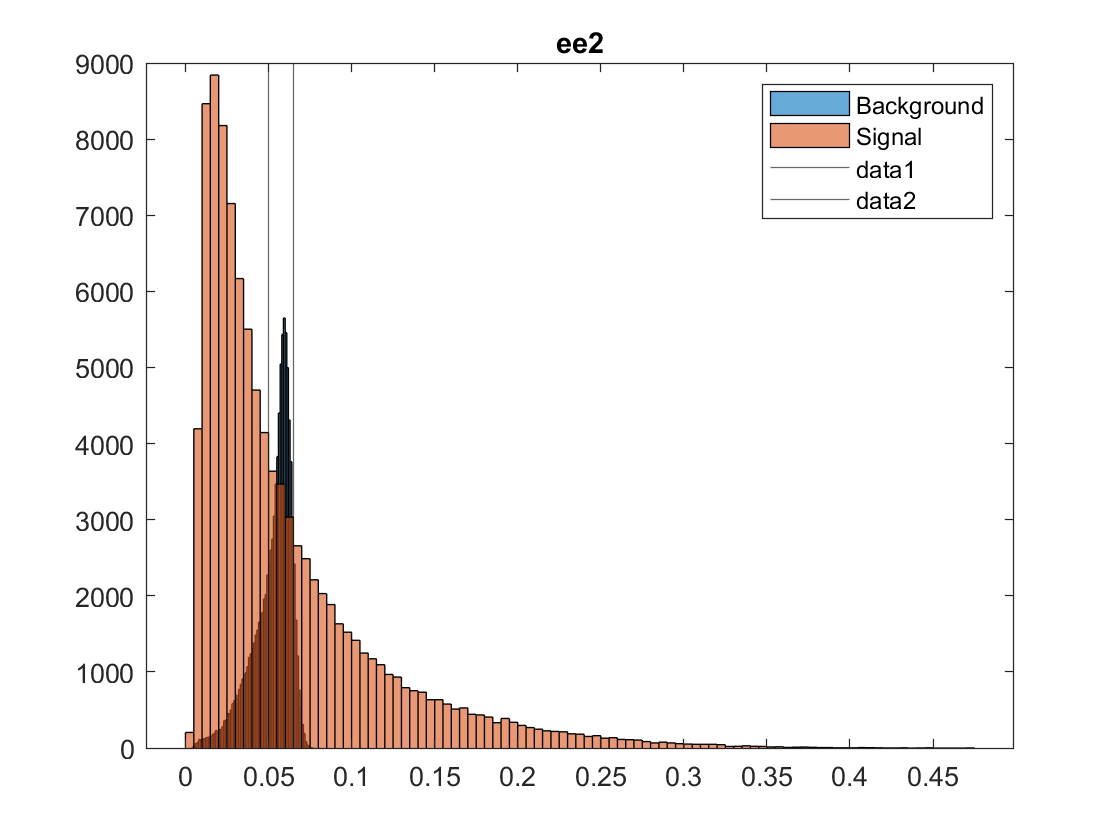

xline(x_range(1))
xline(x_range(2))
hold off

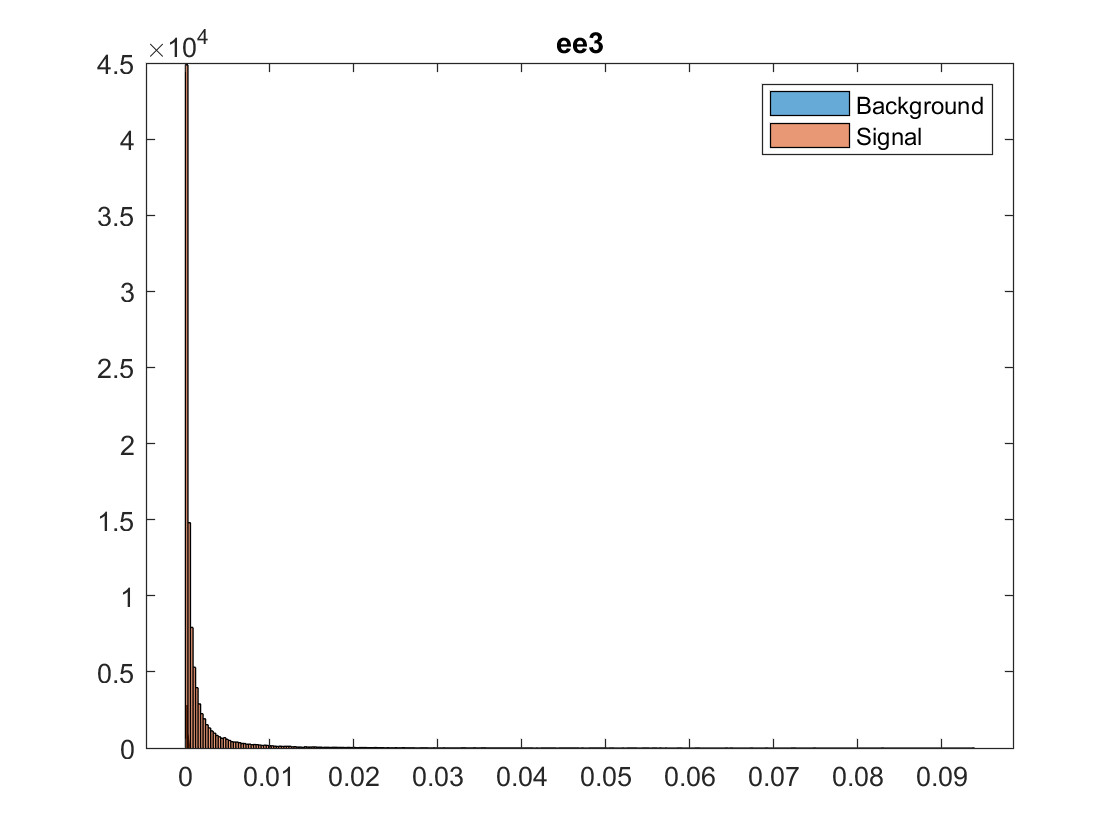


histogram(sig_data(6,:))
title('ee3')
hold on
histogram(bkgnd_data(6,:))
hold off
legend('Background','Signal')

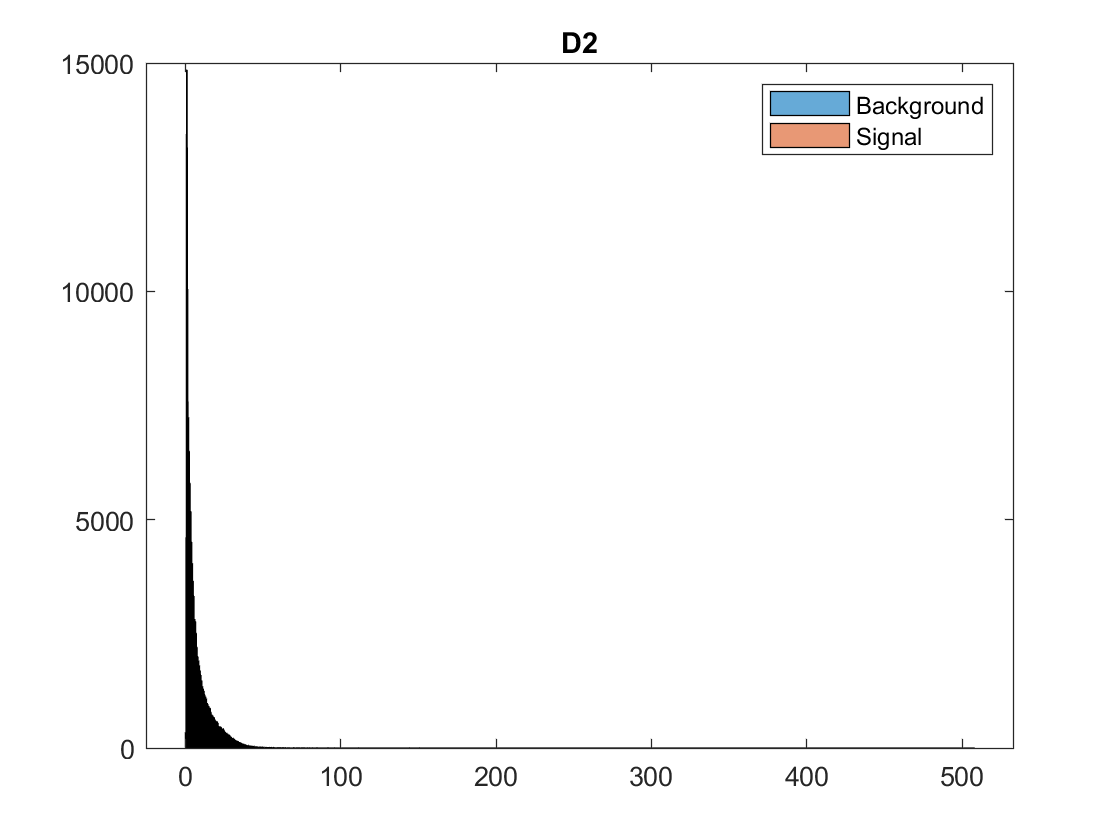


histogram(sig_data(7,:))
title('D2')
hold on
histogram(bkgnd_data(7,:))
hold off
legend('Background','Signal')

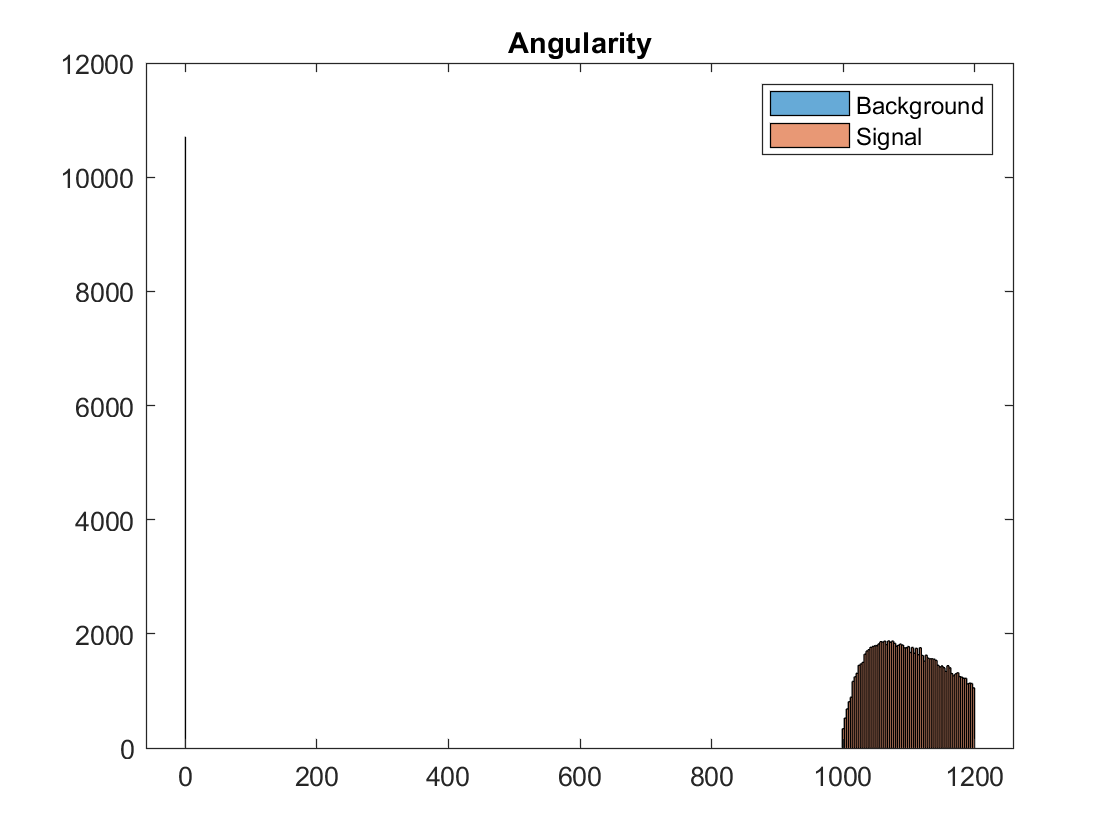


histogram(sig_data(8,:))
title('Angularity')
hold on
histogram(bkgnd_data(1,:))
hold off
legend('Background','Signal')

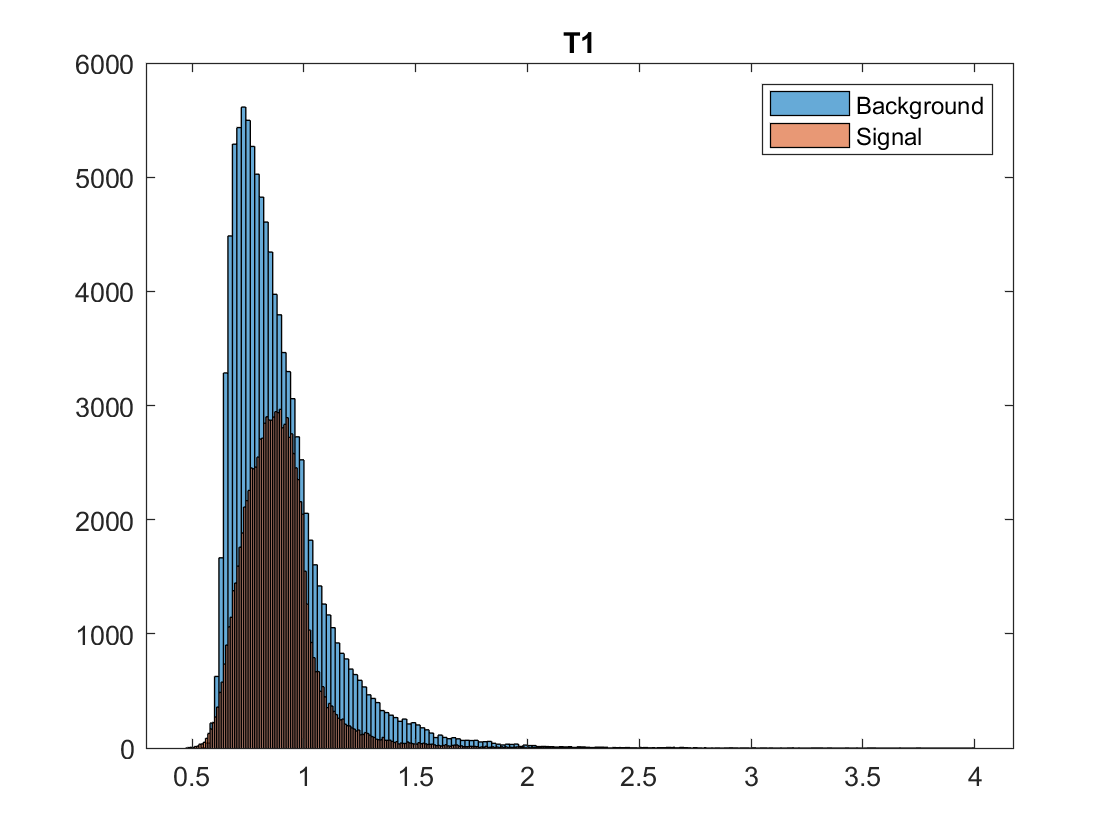


histogram(sig_data(9,:))
title('T1')
hold on
histogram(bkgnd_data(9,:))
hold off
legend('Background','Signal')


histogram(sig_data(10,:))
title('T2')
hold on
histogram(bkgnd_data(10,:))
legend('Background','Signal')
x_range = [0 0.28];
[n_back_t2, n_sig_t2, ratio_t2] = n_calc(bkgnd_data(10,:), sig_data(10,:), x_range)

n_back_t2 = 13174

n_sig_t2 = 59032

ratio_t2 = 4.4809

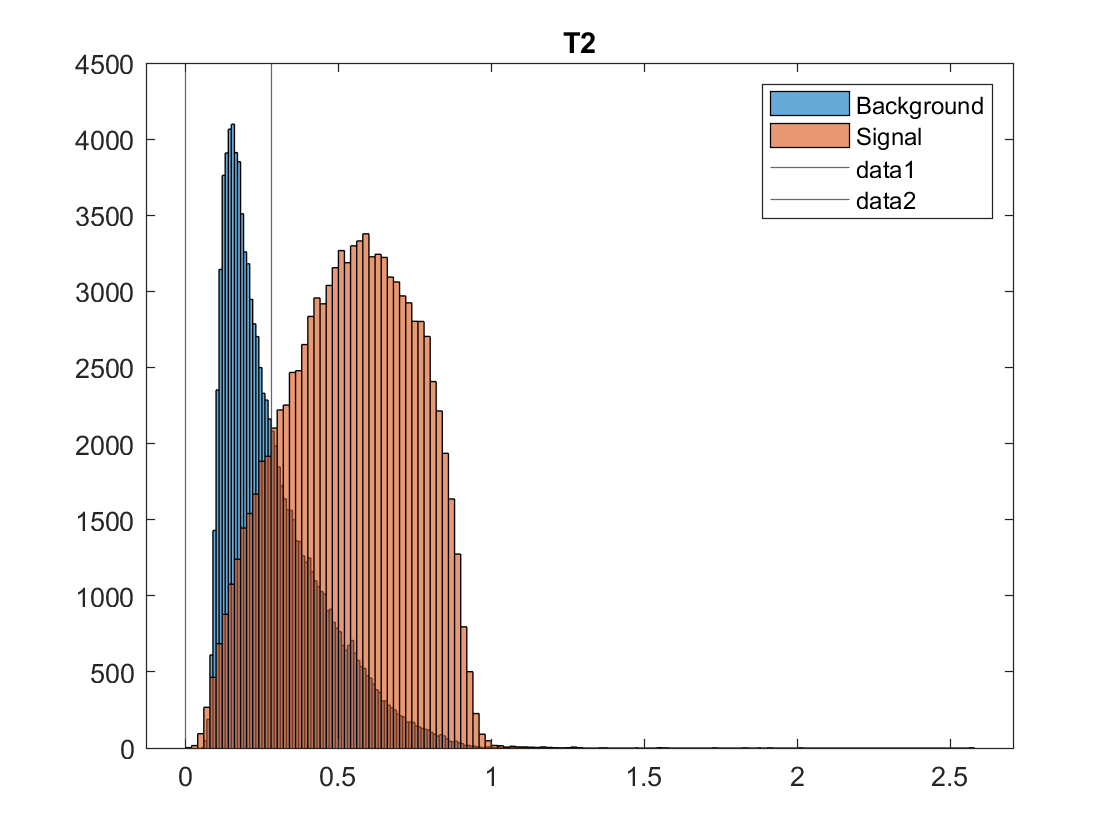

xline(x_range(1))
xline(x_range(2))
hold off


histogram(sig_data(11,:))
title('T3')
hold on
histogram(bkgnd_data(11,:))
legend('Background','Signal')
x_range = [0 0.29];
[n_back_t3, n_sig_t3, ratio_t3] = n_calc(bkgnd_data(11,:), sig_data(11,:), x_range)

n_back_t3 = 27061

n_sig_t3 = 82283

ratio_t3 = 3.0406

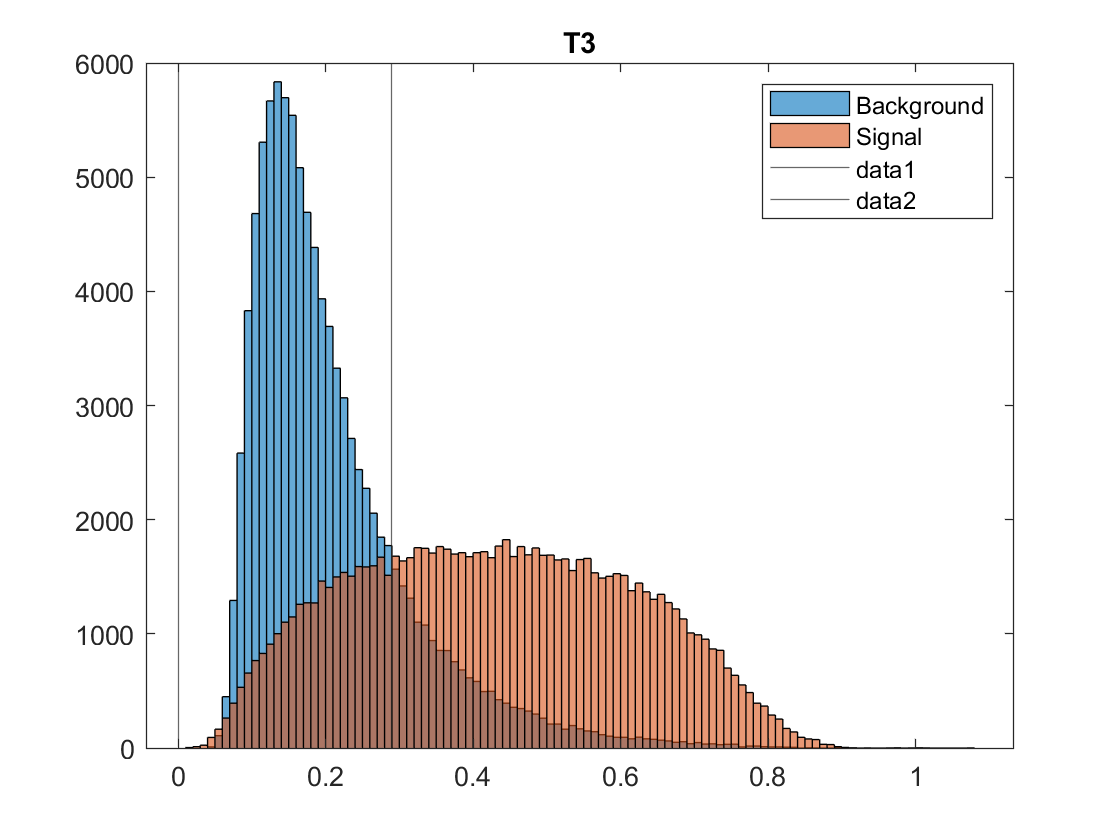

xline(x_range(1))
xline(x_range(2))
hold off


histogram(sig_data(12,:))
title('T21')
hold on
histogram(bkgnd_data(12,:))
legend('Background','Signal')
x_range = [0 0.35];
[n_back_t21, n_sig_t21, ratio_t21] = n_calc(bkgnd_data(12,:), sig_data(12,:), x_range)

n_back_t21 = 13792

n_sig_t21 = 60433

ratio_t21 = 4.3817

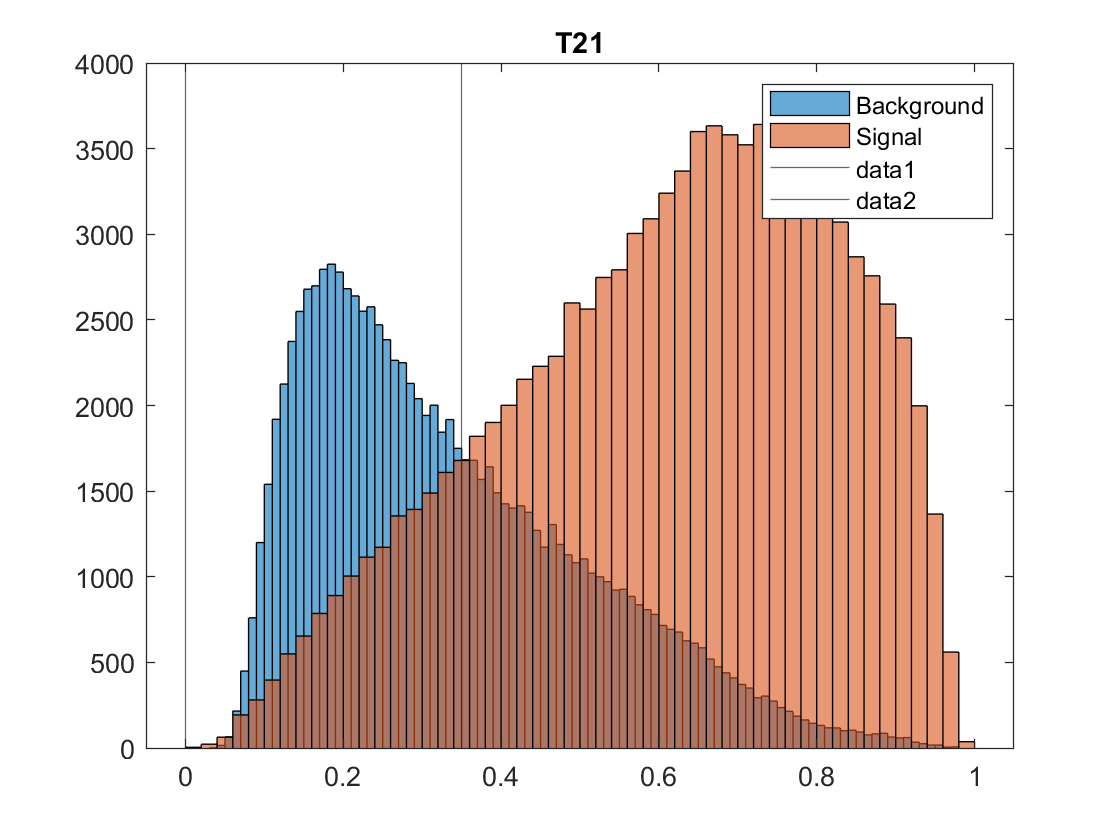

xline(x_range(1))
xline(x_range(2))
hold off


histogram(sig_data(13,:))
title('T32')
hold on
histogram(bkgnd_data(13,:))
legend('Background','Signal')
x_range = [0.315 0.81];
[n_back_t32, n_sig_t32, ratio_t32] = n_calc(bkgnd_data(13,:), sig_data(13,:), x_range)

n_back_t32 = 48607

n_sig_t32 = 58381

ratio_t32 = 1.2011

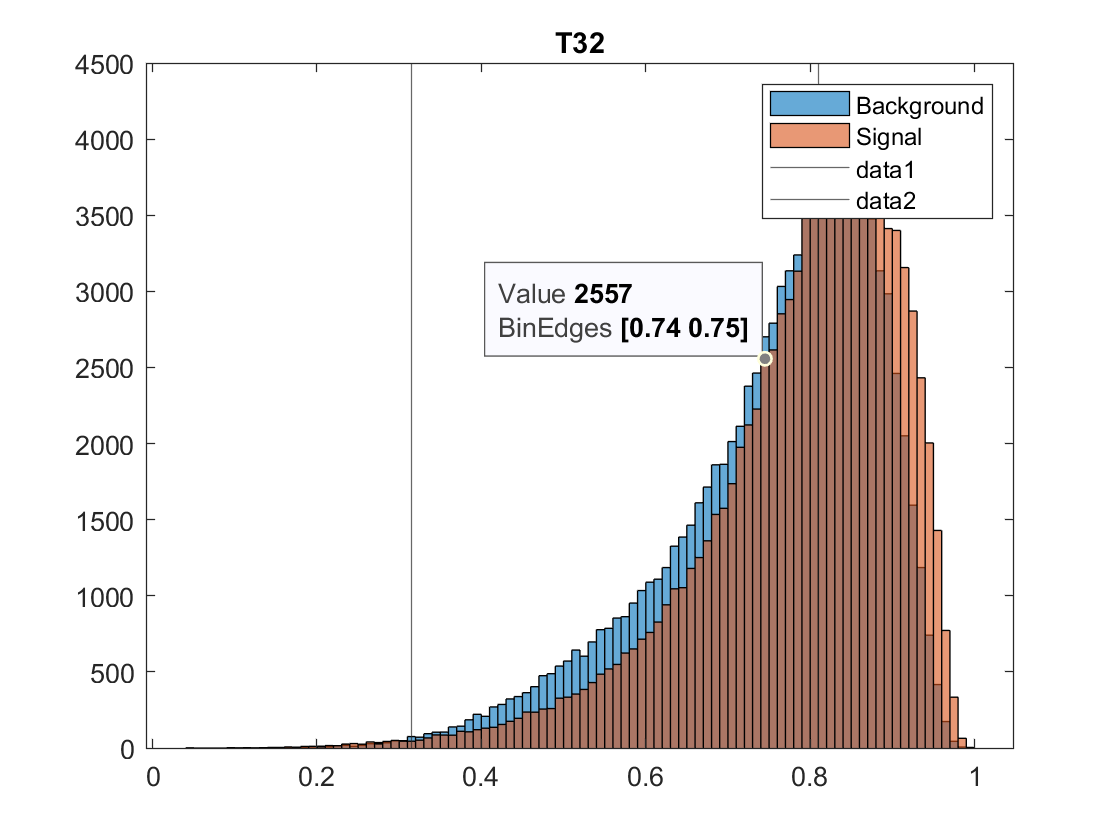

xline(x_range(1))
xline(x_range(2))
hold off


histogram(sig_data(14,:))
title('ktdeltar')
hold on
histogram(bkgnd_data(14,:))
legend('Background','Signal')
x_range = [0.19 0.3];
[n_back_kt, n_sig_kt, ratio_kt] = n_calc(bkgnd_data(14,:), sig_data(14,:), x_range)

n_back_kt = 13788

n_sig_kt = 67704

ratio_kt = 4.9104

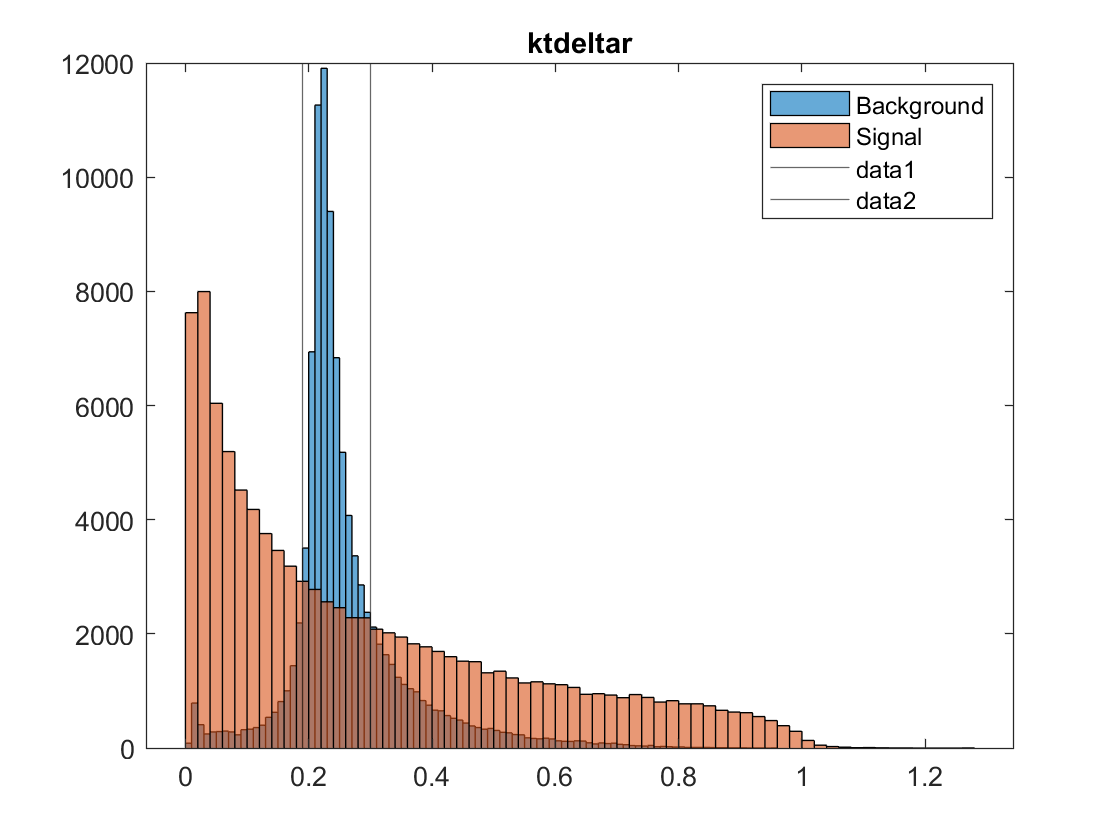

xline(x_range(1))
xline(x_range(2))
hold off

Variable Definitions


$$k_{t}\Delta R = \Delta R \text{ of two subjets within the large-R jet}$$



$$m = \text{mass}$$



$$\tau_{n} = n-\text{ subjettiness}$$



$$\tau_{ij}=\frac{\tau_{i}}{\tau_{j}}$$



$$E_{cfi} = i-\text{th energy correlation function}$$



$$D_{2} = E_{CF3}\times\left(\frac{E_{CF1}}{E_{CF2}}\right)^{3}$$


angularity = angularity


$$p_{T} = \text{transverse momenta - measured in units of } Gev$$



$$eta = \text{sudo rapitity}$$


function [weight_mean] = w_m(x,y)
weight_mean = sum(y.*x)/sum(y);
end

function [n_bkgnd, n_sig, ratio] = n_calc(bkgnd, sig, x_range)
n_bkgnd = 0;
n_sig = 0;
for i = 1:length(bkgnd)
    if bkgnd(i) > x_range(1) && bkgnd(i) < x_range(2)
        n_bkgnd = 1 + n_bkgnd;
    end
    if sig(i) > x_range(1) && sig(i) < x_range(2)
        n_sig = 1 + n_sig;
    end
end
ratio = n_sig/n_bkgnd;
end